clear;
addpath('./lib')
path = './data/';
files = strcat(path, {'2024-01-27-171211-SYSID.csv', '2024-01-27-171456-SYSID.csv', '2024-01-27-171637-SYSID.csv', '2024-01-27-172038-SYSID-TO-USE.csv', '2024-01-27-173926-SYSID-TO-USE.csv'});
raw = cell(size(files));
for i = 1:length(raw)
    data = readmatrix(files{i});
    data = data(1:end-1, :);
    %data = medfilt1(data,50,'truncate');
    raw{i} = data;
end
% raw{:} = raw{:}(1:end-1, :);

close all;
i = 4;
% i2 = 4;
segments = raw{i}(:, 1);
time = raw{i}(:, 2);
throttle = raw{i}(:, 3);
alpha = raw{i}(:, 4);
force = raw{i}(:, 5);
torque = raw{i}(:, 6);
rpm = fillRPM(raw{i}(:, 7));

figure();
subplot(2, 1, 1);
plot(time, throttle);
% hold on
subplot(2, 1, 2);
plot(time, force);
% hold off

% return;





u = [throttle alpha];
y = [force torque rpm];
% nx = 10; % good with tfest
Ts = mean(gradient(time));

nx = 5;



% 
% sys = ssest(u, y, nx, 'Ts', Ts)
% sys.Report.Fit.FitPercent
% tt = timetable(throttle, alpha, force, torque, rpm, TimeStep=seconds(Ts))
% 
% sys2 = ssest(tt, nx, 'OutputName', ["force", "torque", "rpm"], ...
%     'InputName', ["throttle", "alpha"])
% 
% sys2.Report.Fit.FitPercent
% 
% lsim(sys, u, (time(1):Ts:time(end))')
% lsim(sys2, u, (time(1):Ts:time(end))')


% throttle = rpm;
throttleForceTT = timetable(throttle, force, TimeStep=seconds(Ts))

throttleForceTT = 8222×2 timetable
        Time        throttle    force
    ____________    ________    _____

    0 sec              40       2.708
    0.020016 sec       40       2.753
    0.040032 sec       40       2.826
    0.060047 sec       40       2.937
    0.080063 sec       40       3.228
    0.10008 sec        40        3.67
    0.12009 sec        40       3.777
    0.14011 sec        40       3.886
    0.16013 sec        40       3.592
    0.18014 sec        40         4.9
    0.20016 sec        40       3.778
    0.22017 sec        40       4.497
    0.24019 sec        40       4.393
    0.26021 sec        40       4.002
    0.28


% seconds(mean(gradient(raw{i2}(:, 2)))) - seconds(Ts)

% throttleForceValidate = timetable(raw{i2}(:, 3), raw{i2}(:, 5), 'VariableNames',{'throttle','force'}, TimeStep=seconds(Ts))

throttleForceData = iddata(throttleForceTT)

throttleForceData =

Time domain data set with 8222 samples.
Sample time: 0.0200158 seconds          
                                        
Outputs        Unit (if specified)      
   force                                
                                        
Inputs         Unit (if specified)      
   throttle                             
                                        



% opt = ssestOptions

% opt.

% sysThrottleForce = ssest(throttleForceTT, nx, ...
%     'OutputName', "force", ...
%     'InputName', "throttle", ...
%     'Ts',Ts, ...
%     'InitialState','estimate', ...
%     'Focus', 'prediction', ...
%     'Tolerance', 0.0001)

% sysThrottleForce = ssest(throttleForceTT, nx, ...
%     'OutputName', "force", ...
%     'InputName', "throttle", ...
%     'Ts',Ts, ...
%     'Focus', 'prediction', ...
%     'Tolerance', 0.0001)


ns = [2 2 2 0 0 5]; % 69.17
% ns = [10 2 2 0 10 5]; % 69.42
sysThrottleForce = polyest(throttleForceTT, ns,'IntegrateNoise',true, ...
    'OutputName', "force", ...
    'InputName', "throttle", ...
    'Ts',Ts)

sysThrottleForce =
Discrete-time ARIMAX model: A(z)y(t) = B(z)u(t) + [C(z)/(1-z^-1)]e(t)
  A(z) = 1 - 0.1475 z^-1 - 0.2494 z^-2                               
                                                                     
  B(z) = 0.1253 z^-5 + 0.277 z^-6                                    
                                                                     
  C(z) = 1 - 1.063 z^-1 + 0.1629 z^-2                                
                                                                     
Sample time: 0.020016 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=2   nc=2   nk=5
   Number of free coefficients: 6
   Model contains integration on noise channel.
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                       
Estimated using POLYEST on time domain data "throttleForceTT".
Fit to estimation data: 83.27% (prediction focus)             
FPE: 7.309, MSE: 7.298                 



    % 'Feedthrough',1, ...

sysThrottleForce.Report.Fit

ans = struct with fields:
    FitPercent: 83.2728
       LossFcn: 7.1563
           MSE: 7.2985
           FPE: 7.3092
           AIC: 3.9688e+04
          AICc: 3.9688e+04
          nAIC: 1.9891
           BIC: 3.9730e+04


sysThrottleForce.Report.Termination

ans = struct with fields:
                 WhyStop: 'Near (local) minimum, (norm(g) < tol).'
              Iterations: 5
    FirstOrderOptimality: 89.9316
                FcnCount: 12
              UpdateNorm: 0.0012
         LastImprovement: 6.9346e-04


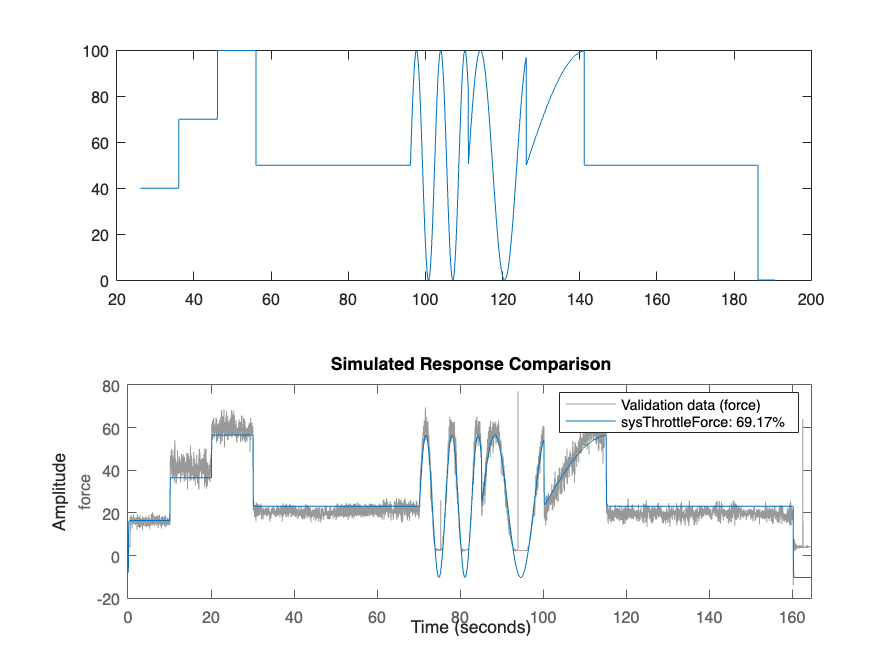


compare(throttleForceTT, sysThrottleForce)

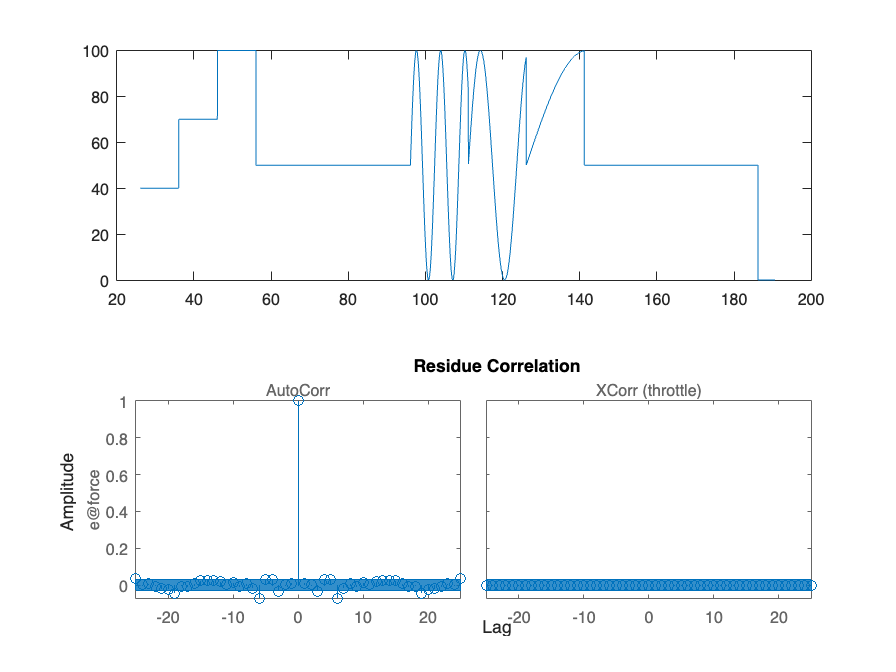


resid(sysThrottleForce, throttleForceTT)


throttleForceTT.Properties.TimeStep

ans = duration
   0.020016 sec



% plot(throttle, force)
% fit(throttle,force,'1./(1+exp(b1+b2*x))','start',[ -1 1])

% compare(sys, u, y, nx)
close all
median(force(1050:1450))

ans = 59.3290

mean(force(1050:1450))

ans = 59.3637

max(force(1050:1450))

ans = 68.6230

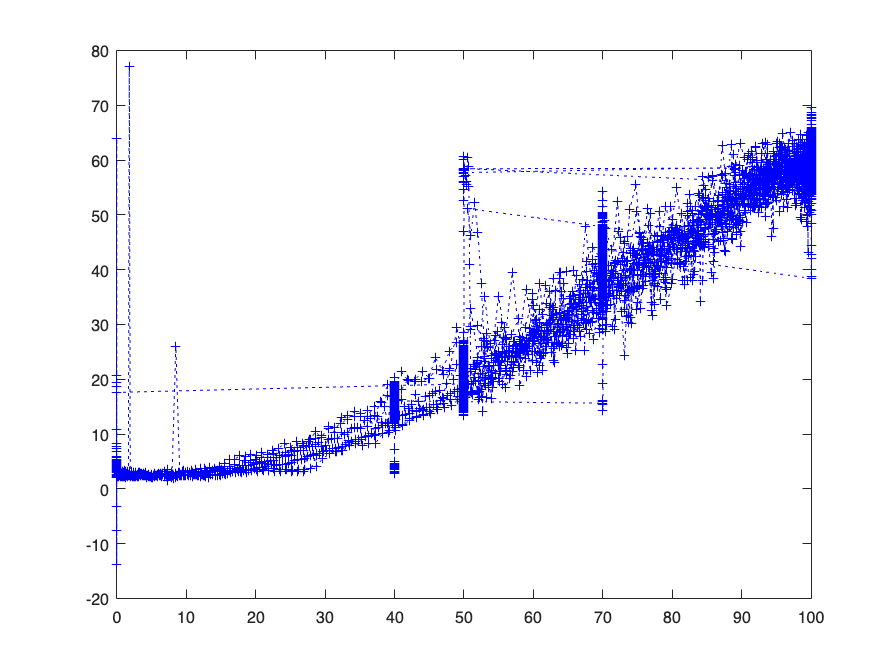



plot(throttle.', force.', 'b+:')

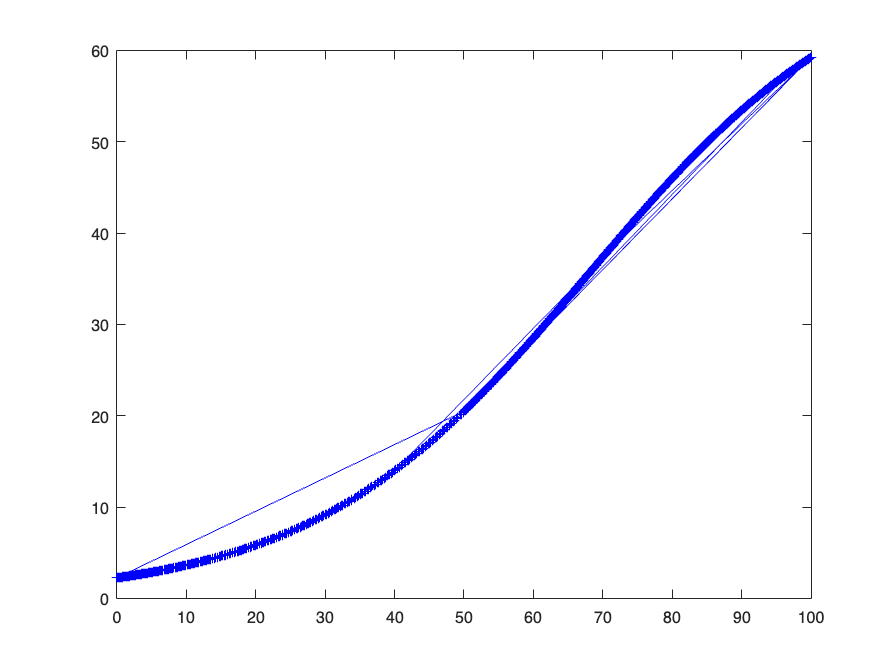

plot(throttle.', throttleForceLogistic(throttle.'), 'b+-')

throttle.'

ans =     40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40    40


force.'

ans =     2.7080    2.7530    2.8260    2.9370    3.2280    3.6700    3.7770    3.8860    3.5920    4.9000    3.7780    4.4970    4.3930    4.0020    4.1550    4.4160    4.5750    4.3030    4.1840    3.9770    3.9580    4.0910    4.1560    4.1810    4.6540    7.2250   11.4910   18.2340   17.8000   17.4980   17.1310   15.4310   14.4960   15.1250   18.2730   15.9070   16.9590   15.7310   17.5740   16.6890   18.9860   17.1120   18.4550   15.9880   18.2030   18.2720   17.4520   16.4400   12.7760   15.3100


throttleForceLogistic(throttle.')

ans =    13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739   13.9739


% throttleForceLogistic(throttle)

throttleForceLogistic(50)

ans = 20.4890

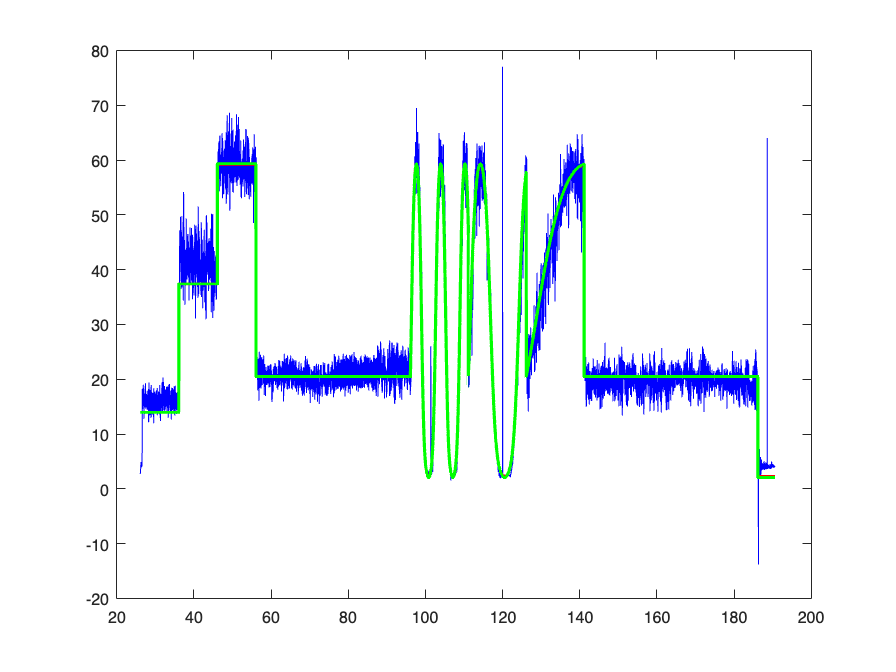


plot(time, force, 'b-')
hold on
plot(time, throttleForceLogistic(throttle), 'r-', LineWidth=2);
plot(time, taylorThrottleForceLogistic(throttle), 'g-', LineWidth=2);
hold off


taylorThrottleForceLogistic(50)

ans = 20.4890

throttleForceLogistic(50)

ans = 20.4890

function force = throttleForceLogistic(throttle)
    a = 71.0072;
    b = 0.0504;
    c = 67.9056;

    % a = 70.7686;
    % b = 0.0501;
    % c = 67.7300;

    % a = 71.2459;
    % b = 0.0506;
    % c = 68.0811;
force = a ./ (1 + exp(-b*(throttle-c)));
end

function result = taylorThrottleForceLogistic(x)
    coefficients = [20.489, 0.734679, 0.00782957, -0.000072076, -2.42549e-6, ...
        -4.00775e-9, 5.40882e-10, 5.56849e-12, -8.11298e-14, -2.01491e-15, ...
        2.13167e-18, 4.97207e-19, 3.72658e-21, -8.64838e-23, -1.62235e-24, ...
        6.74872e-27, 4.4318e-28, 2.16881e-30, -8.69019e-32];
    result = polyval(flip(coefficients), x - 50);
end








